# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

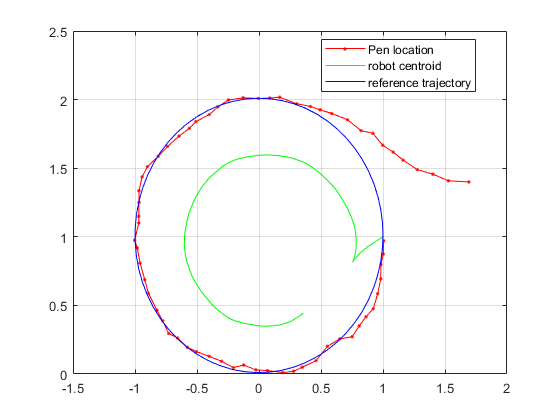

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter

global D h k;
down_sample_amount = 5;

d = 2; % delay amount 

% D = 10; k = 10; h = 0.02;
% position = importdata("CharlotteLogo.mat");
% position = position';

% Circle
D = .8; k = 20; h = 0.01;
position = importdata("position_Array.mat");

l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
 save("UNCCLOGO_downsampled", "position")    
      
state(:,1) =[position(1,1); position(2,1); pi/6];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 

  w_delay = zeros(1,d+1);
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;

for t =1 : T
    n1(t) = 2*randn(1);
    n2(t) = 2*randn(1);

    % x= current state
    
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v(t), w(t)] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x(:,t) = dynamics(x,v(t),w(t),n1(t),n2(t));
    
     linear_vel(t) = v(t)+n1(t);
     angular_vel(t) = w(t)+n2(t);
     
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [(v(t)+n1(t))*cos(state(3,t)); (v(t)+n1(t))*sin(state(3,t)); w(t)+n2(t)];     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1,t)*h;
    yb(t+1) = yb(t) + dot_x(2,t)*h;
    
    if t-d >= 1 && mod(t,d) == 0
        i=0;
    for l = t-d:t
        i = i+1;
        w_delay(i) = dot_x(3,l);
    end
         theta(t+1) = atan2((state(2,t+1-d)-state(2,t-d))/(v(t-d)+n1(t-d)), ...
             (state(1,t+1-d)-state(1,t-d))/(v(t-d)+n1(t-d))) + sum(w_delay)*h;
    elseif t-d < 1
        i=0;
        for l = 1:t
        i = i+1;
        w_delay(i) = dot_x(3,l);
        end
        theta(t+1) = theta(1)+ sum(w_delay)*h;
    else
        for l = t-d:t
        w_delay(i) = dot_x(3,l);
        end
    theta(t+1) = atan2((state(2,t+1-d)-state(2,t-d))/(v(t-d)), ...
             (state(1,t+1-d)-state(1,t-d))/(v(t-d))) + sum(w_delay)*h;
    end

end

figure
plot(xb, yb, '.-','color','r')
hold on
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:),'color','b');
grid on;
legend('Pen location', 'robot centroid', 'reference trajectory', "location", 'best')
hold off

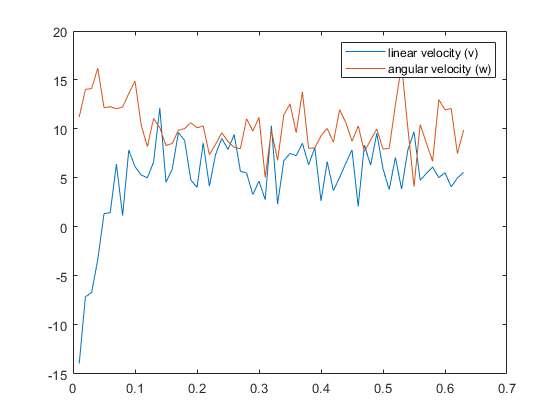


figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('linear velocity (v)', 'angular velocity (w)')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end